## i)

nu_m = 1;
nu_g = 1;
K_g = 3.71;
J_m =3.9E-7;
r_mp = 6.35e-3;
M_c = .57;
M_w = .37;
M = M_c+M_w;
K_t = .00767;
R_m = 2.6;
K_m = .00767;

M_J = nu_g*K_g^2*J_m/(r_mp^2);
m = M + M_J

m = 1.0731

gamma = nu_g*K_g*nu_m*K_t/(R_m*r_mp)

gamma = 1.7235

B_emf = nu_g*K_g^2*nu_m*K_t*K_m/(R_m*r_mp^2)

B_emf = 7.7236

## ii)

k = 10;
B_eq = 5.4;
c = B_eq + B_emf

c = 13.1236

num = gamma;
den = [m c gamma*k 0];
Lpoles = roots(den)

Lpoles =          0
  -10.7328
   -1.4964


Lzeros = roots(num)


Lzeros =

  0×1 empty double column vector



thetaa = (180+360*[0,1,2])/3

thetaa =     60   180   300


sigmaa = (sum(Lpoles)-sum(Lzeros))/3

sigmaa = -4.0764

breakpoints = roots([3*m,2*c,gamma*k])

breakpoints =    -7.4326
   -0.7203


w = [0; roots([-1 0 gamma*k])]

w =          0
    4.1516
   -4.1516


ki = c*w(2)^2/gamma

ki = 131.2356

num = [gamma];
den = [m, c, gamma*k, 0];
L = tf(num,den)

L =
 
               1.724
  -------------------------------
  1.073 s^3 + 13.12 s^2 + 17.24 s
 
Continuous-time transfer function.



% rlocus(L)

## iii)

Mp = 2; ts = .5;
zd = -log(Mp/100)/sqrt(pi^2+log(Mp/100)^2)

zd = 0.7797

wnd = 4/(zd*ts)

wnd = 10.2603

sd = [-zd*wnd + 1i * wnd * sqrt(1-zd^2); -zd*wnd - 1i * wnd * sqrt(1-zd^2)]

sd =   -8.0000 + 6.4245i
  -8.0000 - 6.4245i


num2 = [gamma]; den2 = [m c 0];
G = tf(num2,den2);
gpole = roots(den2)

gpole =          0
  -12.2293


sdd = sd(1);
theta1 = rad2deg(atan2(imag(sdd),real(sdd)))

theta1 = 141.2334

theta2 = rad2deg(atan(imag(sdd)/(-gpole(2)+real(sdd))))

theta2 = 56.6429

Gangle = -theta1 -theta2

Gangle = -197.8763

% Gangle = rad2deg(-(atan2(imag(sdd),real(sdd)) + atan2(imag(m*sdd+c),real(m*sdd+c))))
phi = -180 - Gangle

phi = 17.8763

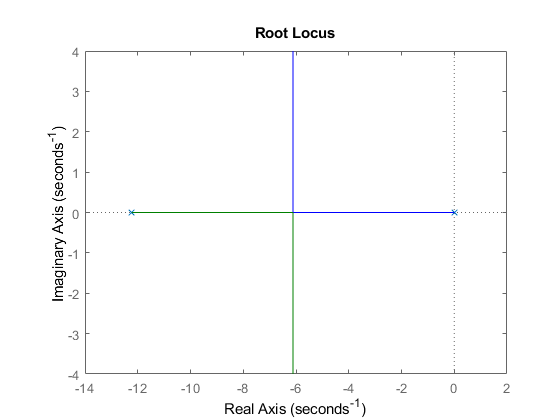

rlocus(G)

zd = -(imag(sdd)/tand(phi)-real(sdd))

zd = -27.9188

kd = norm(m*sdd^2+c*sdd)/norm(sdd+zd)/gamma

kd = 1.3466

% kd = 1.47;
fc = 1;
kp = -zd*kd;
ki=0;
% stepinfo(out.x.data,out.x.time)

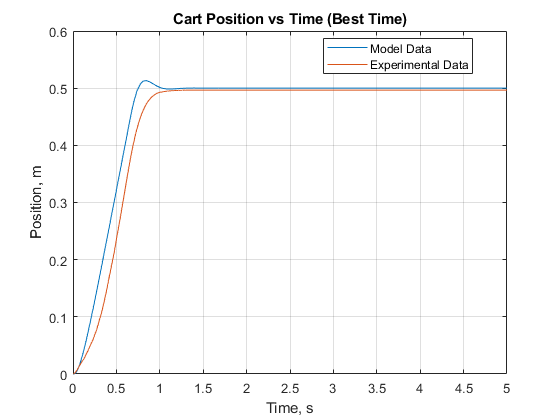

plot(out.sat.time,out.sat.data)
hold on
% plot(out.nosat.time,out.nosat.data)
% plot(linspace(0,2.705,length(v.signals.values)),y.signals.values)
grid on
plot(Cartposition(:,1),Cartposition(:,2))
title("Cart Position vs Time (Best Time)")
xlabel("Time, s")
ylabel("Position, m")
legend("Model Data",'Experimental Data','Location','Best')
xlim([0,5])

hold off
diff(out.sat.data)/abs(9.9861-10.0000)

plot(out.satv.time,out.satv.data)
hold on
plot(out.nosatv.time,out.nosatv.data)
plot(linspace(0,2.705,length(v.signals.values)),v.signals.values)
grid on
title("Voltage vs Time")
xlabel("Time, s")
ylabel("Voltage, V")
legend("Model Data, Saturation",'Model Data, No Saturation','Experimental Data','Location','Best')
xlim([0,2])
ylim([-4,20])
hold off

hold off

% plot(out.e.time,out.e.data)
% hold on
% time = 0:.001:6.2-.001;
% plot(time,e.signals.values)
% grid on
% title("Error vs Time")
% xlabel("Time, s")
% ylabel("Error, m")
% legend("Model Data",'Experimental Data','Location','Best')
% xlim([0,7])
% hold off